### Problema 1

f = @(x) 2*x.*besselj(1,x) - besselj(0,x);
syms t
f_t = f(t);
fd_t = diff(f_t, t)

$$fd\_t = 3\,J_{1}\left(t\right)-2\,t\,\left(\frac{J_{1}\left(t\right)}{t}-J_{0}\left(t\right)\right)$$

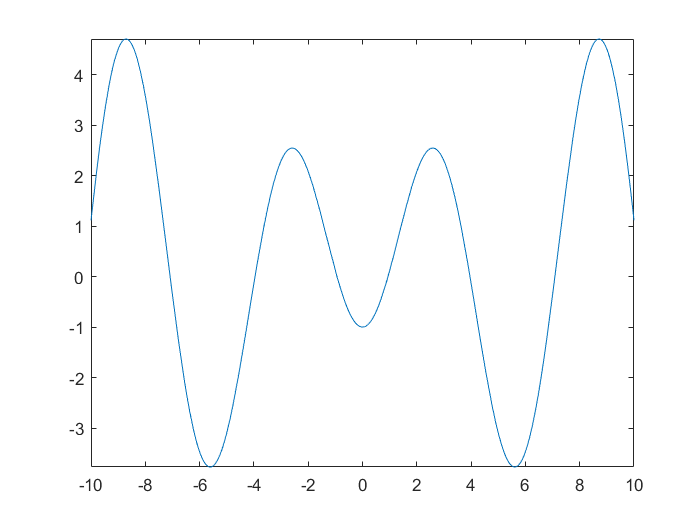

% Derivata lui f
fd = @(x) 3 * besselj(1, x) - 2 * x .* (besselj(1, x) ./ x - besselj(0, x));

fplot(f, [-10, 10]);

Graficul ne spune ca cele mai mici radacini pozitive se afla in jur de 1, 4 si 7

err = 1e-6;
[z1n, ni1n] = Newton(f, fd, 1, err, err)

z1n = 0.9408

ni1n = 3

[z2n, ni2n] = Newton(f, fd, 4, err, err)

z2n = 3.9594

ni2n = 3

[z3n, ni3n] = Newton(f, fd, 7, err, err)

z3n = 7.0864

ni3n = 3

[z1s, ni1s] = secant(f, 1, 2, err, err)

z1s = 0.9408

ni1s = 4

[z2s, ni2s] = secant(f, 3, 4, err, err)

z2s = 3.9594

ni2s = 4

[z3s, ni3s] = secant(f, 7, 8, err, err)

z3s = 7.0864

ni3s = 4

% Verificare
disp([f(z1n), f(z2n), f(z3n)])

   1.0e-13 *

    0.3508   -0.0272    0.0061



disp([f(z1s), f(z2s), f(z3s)])

   1.0e-10 *

    0.0009    0.0271    0.3891



### Problema 2

% x(1) - alpha, x(2) - beta, x(3) - gamma
F = @(x) [
    x(1)*exp(x(2)*1) + x(3)*1 - 10;
    x(1)*exp(x(2)*2) + x(3)*2 - 12;
    x(1)*exp(x(2)*3) + x(3)*3 - 18;
];

% Jacobiana
J = @(x) [
    exp(x(2)*1), x(1)*1*exp(x(2)*1), 1;
    exp(x(2)*2), x(1)*2*exp(x(2)*2), 2;
    exp(x(2)*3), x(1)*3*exp(x(2)*3), 3;
];

x0 = [5, 0.5, -1]; % Daca nu incep cu o aproximare cat de cat buna nu converge si rezulta
% in erori legate de conditionarea matricilor

err = 1e-2;
[z, ni] = Newton(F, J, x0, err, err)

z =    10.6667
    0.4055
   -6.0000


ni = 4

% Verificare
f = @(x) z(1) .* exp(z(2) .* x) + z(3) .* x;
disp([f(1), f(2), f(3)])

   10.0000   12.0000   18.0001



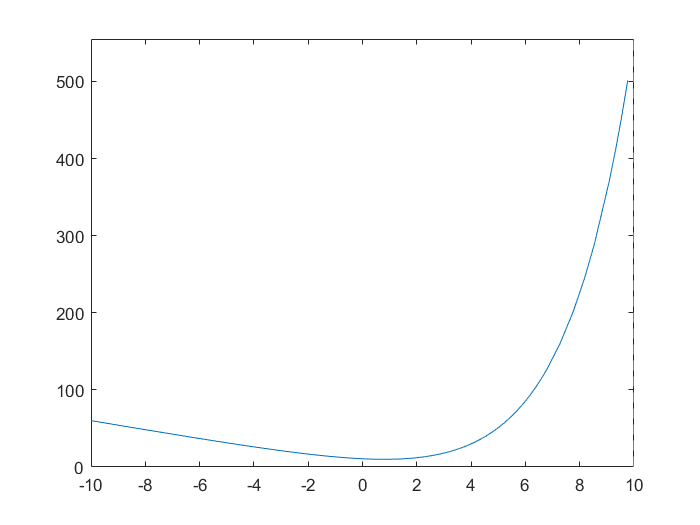

fplot(f, [-10, 10])